# lTEMPLATE FOR DATA LABEL

Version: 1.0

Date: 20/07/2022 

## EXPLANATION:

 At the beginning of each experiment you have to start from the STEP 1.

For the second suture or more from the same experiment, you have to start from the STEP 4 for each suture.

___________________

## STEP 1:   INITIALIZE THE PROJECT WITH THE NUMBER OF THE EXPERIMENT

- **Write the number of the experiment (line 8)**

% DO NOT CHANGE %--------------------
clc
clear all
%-----------------------------------


%%  WRITE HERE THE NUMBER OF THE EXPERIMENT   %%
experimiento = 2;  % <-----------------
%%%%%%%

    **2. Run this section (one click on the blue lines on the left side of the number of the lines)**

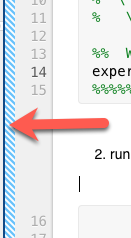

Do not change anything else in this step

% DO NOT CHANGE %-----------------------
carpetaExp = sprintf('exp%d',experimiento);
RawFiles = strcat(pwd,'\',carpetaExp,'\RawFiles');
SutureFiles = strcat(pwd,'\',carpetaExp);
mkdir(SutureFiles,'Sutures');

rawFile_APR = fullfile(RawFiles, sprintf('single_suture_APR_exp%d',experimiento));
rawFile_APL = fullfile(RawFiles, sprintf('single_suture_APL_exp%d',experimiento));
rawFile_IMU = fullfile(RawFiles, sprintf('single_suture_IMU_exp%d',experimiento));
datos_finales_AW = readtable(rawFile_APR);

datos_finales_sensor = readtable(rawFile_IMU);

datos_finales_AW_left = readtable(rawFile_APL);

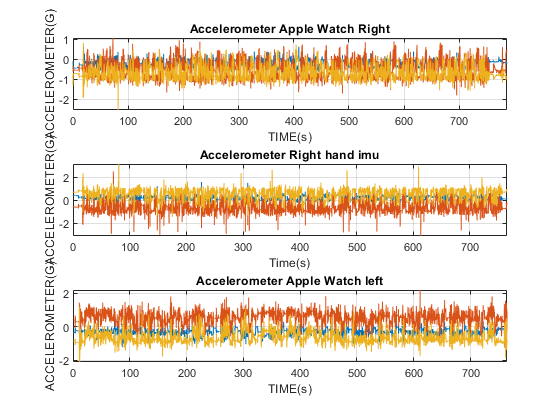

f = 50;
T = 1/50;

%CORRELACION AUTOMATICA
Corr_APR_IMU = Correlacion(datos_finales_AW.accelerometerAccelerationX_G_,datos_finales_sensor.ax_g_);
Corr_APL_IMU = Correlacion(datos_finales_AW_left.accelerometerAccelerationX_G_,datos_finales_sensor.ax_g_);
datos_finales_AW_left([1:Corr_APL_IMU],:) = [];
datos_finales_AW([1:Corr_APR_IMU],:) = [];
figure()
total_time1_APR = length(datos_finales_AW.accelerometerAccelerationX_G_)*T;
time_vector1_APR = linspace(0,total_time1_APR,length(datos_finales_AW.accelerometerAccelerationX_G_));
subplot(3,1,1)
plot(time_vector1_APR,datos_finales_AW.accelerometerAccelerationX_G_,time_vector1_APR,datos_finales_AW.accelerometerAccelerationY_G_,time_vector1_APR,datos_finales_AW.accelerometerAccelerationZ_G_)
title ('Accelerometer Apple Watch Right')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

total_time1_sensor = length(datos_finales_sensor.ax_g_)*T;
time_vector1_sensor = linspace(0,total_time1_sensor,length(datos_finales_sensor.ax_g_));
subplot(3,1,2)
plot(time_vector1_sensor,datos_finales_sensor.ay_g_,time_vector1_sensor,datos_finales_sensor.ax_g_,time_vector1_sensor,datos_finales_sensor.az_g_)
title ('Accelerometer Right hand imu')
ylabel('ACCELEROMETER(G)')
xlabel('Time(s)')
xlim tight
grid on
total_time1_APL = length(datos_finales_AW_left.accelerometerAccelerationX_G_)*T;
time_vector_APL = linspace(0,total_time1_APL,length(datos_finales_AW_left.accelerometerAccelerationX_G_));
subplot(3,1,3)
plot(time_vector_APL,datos_finales_AW_left.accelerometerAccelerationX_G_,time_vector_APL,datos_finales_AW_left.accelerometerAccelerationY_G_,time_vector_APL,datos_finales_AW_left.accelerometerAccelerationZ_G_)
title ('Accelerometer Apple Watch left')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

%-------------------------------------







______

## STEP 2:  CUT THE SIGNALS WITH A COMMON POINT

- **Find the initial value where all the signals are going to cut off.**

                It can be when **she raises his hands**.

                It can be when **she starts to move their hands**

           Look at the first graph on the right (The first title is: Accelerometer Apple Watch Right). You can expand it by pressing on the upper-right corner.

%%  WRITE HERE THE TIME  - USE DOT FOR DECIMALS (.)   %%
tiempo_inicio = 18.78;

    **2. Run this section (one click on the blue lines on the left side of the number of the lines)**

      **3. Verify if the cut off is over the right place.** (DO NOT CHANGE THE FOLLOWING LINES)

    If you want to change the value, you have to write again and run the section

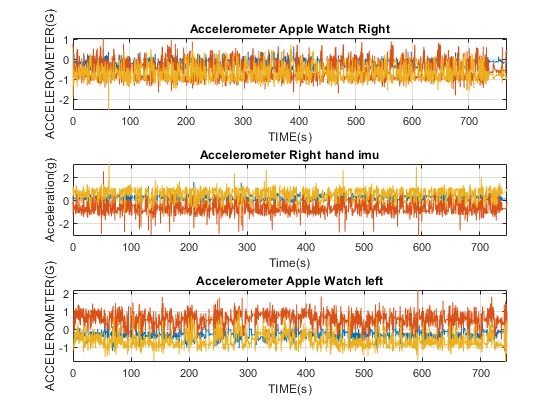

% DO NOT CHANGE %-----------------------
%%%% estas graficas son para validar si quedo cortado en el punto indicador
[result] = find(abs(time_vector1_APR-tiempo_inicio) <0.01);
datos_finales_AW_left([1:result],:) = [];
datos_finales_AW([1:result],:) = [];
datos_finales_sensor([1:result],:) = [];
figure()
total_time1_APR = length(datos_finales_AW.accelerometerAccelerationX_G_)*T;
time_vector1_APR = linspace(0,total_time1_APR,length(datos_finales_AW.accelerometerAccelerationX_G_));
subplot(3,1,1)
plot(time_vector1_APR,datos_finales_AW.accelerometerAccelerationX_G_,time_vector1_APR,datos_finales_AW.accelerometerAccelerationY_G_,time_vector1_APR,datos_finales_AW.accelerometerAccelerationZ_G_)
title ('Accelerometer Apple Watch Right')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

total_time1_sensor = length(datos_finales_sensor.ax_g_)*T;
time_vector1_sensor = linspace(0,total_time1_sensor,length(datos_finales_sensor.ax_g_));
subplot(3,1,2)
plot(time_vector1_sensor,datos_finales_sensor.ay_g_,time_vector1_sensor,datos_finales_sensor.ax_g_,time_vector1_sensor,datos_finales_sensor.az_g_)
title ('Accelerometer Right hand imu')
ylabel('Acceleration(g)')
xlabel('Time(s)')
xlim tight
grid on
total_time1_APL = length(datos_finales_AW_left.accelerometerAccelerationX_G_)*T;
time_vector_APL = linspace(0,total_time1_APL,length(datos_finales_AW_left.accelerometerAccelerationX_G_));
subplot(3,1,3)
plot(time_vector_APL,datos_finales_AW_left.accelerometerAccelerationX_G_,time_vector_APL,datos_finales_AW_left.accelerometerAccelerationY_G_,time_vector_APL,datos_finales_AW_left.accelerometerAccelerationZ_G_)
title ('Accelerometer Apple Watch left')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

syncFiles =strcat(pwd,'\',sprintf('exp%d',experimiento),'\Log');
mkdir(syncFiles);

syncvar = fullfile(syncFiles, sprintf('single_suture_SyncVar_exp%d.mat',experimiento));

save(syncvar,"-mat");

fprintf('CUT VIDEO ON:  %2.2f \n',tiempo_inicio)

CUT VIDEO ON:  18.78 


## ______

## STEP 3:   CUT THE VIDEO (USING FREEVIDEOCUTTER)

-  CUT THE VIDEO AT THE SAME TIME THAT YOU SELECTED IN THE STEP 2

## _____________________   START FROM HERE FOR EACH SUTURE

__________

## STEP 4:  FIND THE KEY POINTS FOR THE SUTURE

- **Wirte the number of the SUTURE**

The number of the suture starts with 1 for the first one of each experiment

%%%%% WRITE THE SUTURE NUMBER FROM THIS EXPERIMENT %%%%%%%
sutura = 10; % <-----------------

       ** 2. Open the cut video from STEP 3 of the current experiment. **The video will be the same for all sutures from the same experiment

    **    3. Watch the video and note the time where the important things happen**

%%%%% WRITE THE RANGE OF VALUES HERE %%%%%%%
% .. = [MINUTE SECOND]


% WRITE THE TIME FOR THE BEGINNING OF THE SUTURE (THE PROCEDURE)
inicioSutura = [5 58.40];

% WRITE THE TIME WHEN THE NEEDLE IS INSERTED
inicioAguja = [5 59.65];
finalAguja = [6 3.15];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% VUELTAS %%%%%%%%%%%%%%%%%%%%%
% YOU CAN ADD OR REMOVE THE PACKAGE OF LINES IF IT'S NECESSARY 

%--
numVuelta = 1;
inicioVueltas(numVuelta,:) = [6 5.40];
finalVueltas(numVuelta,:) = [6 6.23];
orientacionVueltas(numVuelta) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
%--

%--
numVuelta = 2;
inicioVueltas(numVuelta,:) = [6 8.48];
finalVueltas(numVuelta,:) = [6 10.73];
orientacionVueltas(numVuelta) = 0;
%--

%--
numVuelta = 3;
inicioVueltas(numVuelta,:) = [6 12.56];
finalVueltas(numVuelta,:) = [6 13.06];
orientacionVueltas(numVuelta) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
%--


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% FIN VUELTAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
finalSutura = [6 21.15];


**4. Run this section (one click on the blue lines on the left side of the number of the lines)**

**5. CHECK THE GRAPH WITH COLORS IF EVERYTHING IS FINE**

DO NOT CHANGE FROM HERE

% DO NOT CHANGE %-----------------------
%%%%%%%%%%%%%%%%% no cambiar guarado de variables %%%%%%%%%%%%%%%%
SutureFolder = fullfile(strcat(SutureFiles,'\Sutures'),sprintf('Suture%d',sutura));
mkdir(SutureFolder);

mkdir(SutureFolder, "log")

mkdir(SutureFolder, "img")

mkdir(SutureFolder, "Negative")

mkdir(SutureFolder, "Positive")

mkdir(strcat(SutureFolder,'\Positive'),"AgujaEntraSale")

mkdir(strcat(SutureFolder,'\Positive'),"Vueltas")

mkdir(strcat(SutureFolder,'\Positive'),"VueltasAdelante")

mkdir(strcat(SutureFolder,'\Positive'),"VueltasAtras")

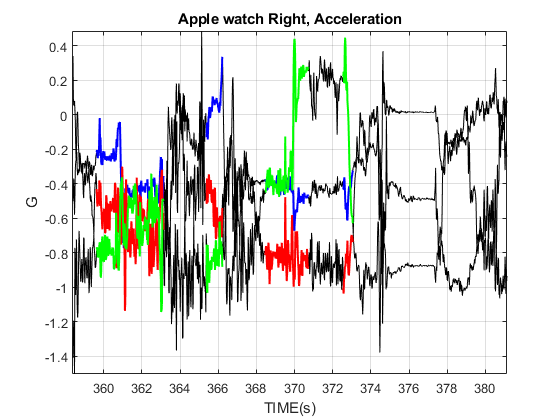

for w=1:length(orientacionVueltas)
    if orientacionVueltas(w) == 0
        [VueltasAbajo_APL,VueltasAbajo_APR,VueltasAbajo_IMU] = Guardado(inicioVueltas(w,:),finalVueltas(w,:),datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
        VueltasAbajo = fullfile(strcat(SutureFolder,'\Positive\VueltasAtras'), sprintf('Range_VueltasAtras%d_Suture%d_exp%d.mat',w,sutura,experimiento));
        save(VueltasAbajo,"VueltasAbajo_APL",'VueltasAbajo_APR','VueltasAbajo_IMU',"-mat");
    else 
        [VueltasArriba_APL,VueltasArriba_APR,VueltasArriba_IMU] = Guardado(inicioVueltas(w,:),finalVueltas(w,:),datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
        VueltasArriba = fullfile(strcat(SutureFolder,'\Positive\VueltasAdelante'),sprintf('Range_VueltasAdelante%d_Suture%d_exp%d.mat',w,sutura,experimiento));
        save(VueltasArriba,"VueltasArriba_APL",'VueltasArriba_APR','VueltasArriba_IMU',"-mat");
    end
end
[Positive_Aguja_APL,Positive_Aguja_APR,Positive_Aguja_IMU] = Guardado(inicioAguja,finalAguja,datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
Aguja = fullfile((strcat(SutureFolder,'\Positive\AgujaEntraSale')),sprintf('Positive_Aguja_Suture%d_exp%d.mat',sutura,experimiento));
save(Aguja,'Positive_Aguja_APL','Positive_Aguja_APR','Positive_Aguja_IMU');

%%%% guarda el rango de inicio y final de todas las vueltas incluyendo los negativos %%%%%
[Vueltas_APL,Vueltas_APR,Vueltas_IMU] = Guardado(inicioVueltas(1,:),finalVueltas(length(finalVueltas),:),datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
Vueltas = fullfile(strcat(SutureFolder,'\Positive\Vueltas'), sprintf('Range_Vueltas_Suture%d_exp%d.mat',sutura,experimiento));
save(Vueltas,"Vueltas_APL",'Vueltas_APR','Vueltas_IMU',"-mat");
%%% guarda el rango desde el inicio de la sutura al final %%%
[SutureRange_APL,SutureRange_APR,SutureRange_IMU] = Guardado(inicioSutura,finalSutura,datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
Range_Suture = fullfile(strcat(SutureFolder,'\log'), sprintf('Range_Suture%d_exp%d.mat',sutura,experimiento));
save(Range_Suture,"SutureRange_APL",'SutureRange_APR','SutureRange_IMU',"-mat");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%% NO MODIFICAR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% conversion a segundo y guardado de variables
inicios=[];
finales = [];
for n=2:length(orientacionVueltas)+1
    for j=1:n-1
    tiempo = ConvTime(inicioVueltas(j,:));
    inicios(n) = tiempo;  
    end
end
finales(1) = ConvTime(inicioSutura);
inicios(1) = ConvTime(inicioAguja);
finales(2) = ConvTime(finalAguja);
sizeOfinicios = length(inicios);             
inicios(sizeOfinicios+1) = ConvTime(finalSutura);
for n=3:length(finalVueltas)+2
    for j=1:n-2
    tiempo = ConvTime(finalVueltas(j,:));
    finales(n) = tiempo;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Grafica para comprobar que los puntos quedaron bien marcado y guardar
%%%% negativos %%%%%%
figure()
for n=1:numel(inicios)
    a_num = inicios(n);
    b_num = finales(n);
    [SutureRange_Negative_APL,SutureRange_Negative_APR,SutureRange_Negative_IMU] = GuardadoNegativo(a_num,b_num,datos_finales_AW_left,datos_finales_AW,datos_finales_sensor);
    Range_Suture_negative = fullfile(strcat(SutureFolder,'\Negative'), sprintf('Range_Suture%d_Negative%d_exp%d.mat',sutura,n,experimiento));
    save(Range_Suture_negative,"SutureRange_Negative_APL",'SutureRange_Negative_APR','SutureRange_Negative_IMU',"-mat");
end    
z=GuardarGraficasPDF(datos_finales_AW,datos_finales_AW_left,datos_finales_sensor,time_vector_APL,time_vector1_APR,time_vector1_sensor,inicios,finales,SutureFolder);

AllVar = fullfile(strcat(SutureFolder,'\log'), sprintf('AllVar_Suture%d_exp%d.mat',sutura,experimiento));
save(AllVar,"-mat");
Array_iniFin = fullfile(strcat(SutureFolder,'\log'), sprintf('Arrays_IniFin_Suture%d_exp%d.mat',sutura,experimiento));
save(Array_iniFin,"-mat");